# Time Simulation of an ECM model

The function :battmo:`createParametersECM` setups an data set for the ECM model. The structure `jsonstruct` contains values of the ECM parameters (resistances, capicaties, ...) that depend on the frequency. See below for the plot of the values

jsonstruct = createParametersECM();

Setup the ECM model

inputparams =  EquivalentCircuitModelInputParams(jsonstruct);
model =  EquivalentCircuitModel(inputparams);

Review of the model parameters

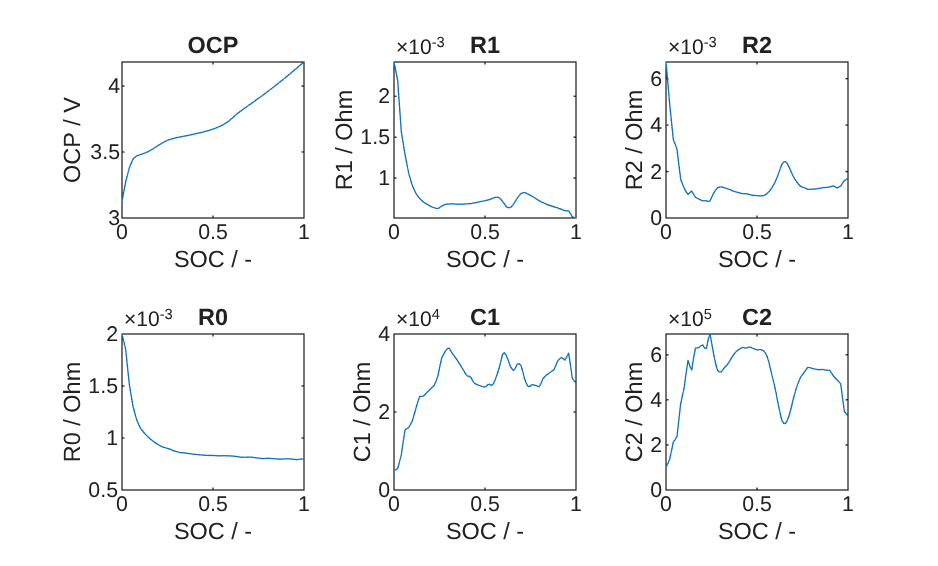

soc = linspace(0, 1, 100);

figure
tiledlayout(2, 3, 'tileindexing', 'columnmajor');

nexttile
plot(soc, model.OCPfunc(soc))
title('OCP')
xlabel('SOC / -')
ylabel('OCP / V');

nexttile
plot(soc, model.R0func(soc))
title('R0')
xlabel('SOC / -')
ylabel('R0 / Ohm');

nexttile
plot(soc, model.R1func(soc))
title('R1')
xlabel('SOC / -')
ylabel('R1 / Ohm');

nexttile
plot(soc, model.C1func(soc))
title('C1')
xlabel('SOC / -')
ylabel('C1 / Ohm');

nexttile
plot(soc, model.R2func(soc))
title('R2')
xlabel('SOC / -')
ylabel('R2 / Ohm');

nexttile
plot(soc, model.C2func(soc))
title('C2')
xlabel('SOC / -')
ylabel('C2 / Ohm');

The input current has been passed to the model

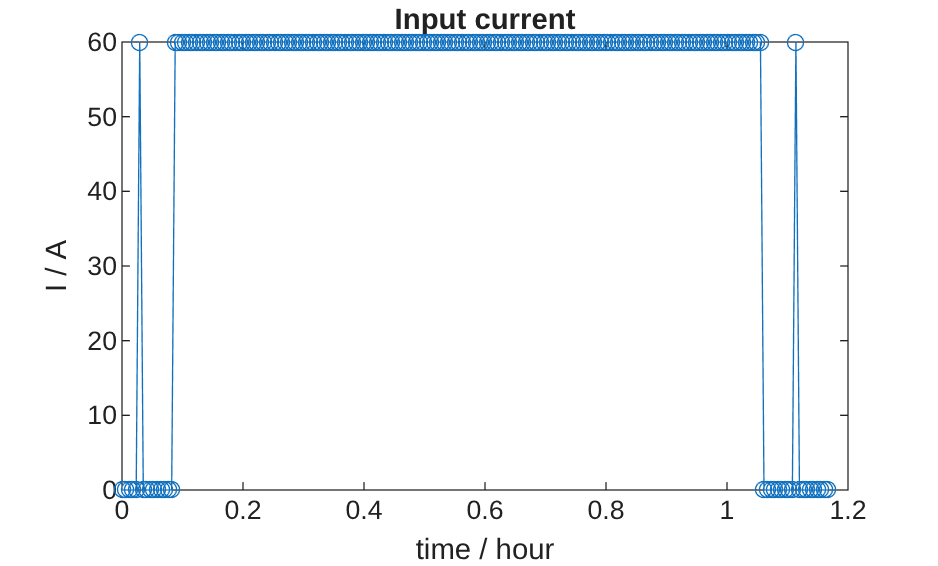

figure
totalTime = model.totalTime;
t = linspace(0, totalTime, 200); 
plot(t/hour, model.Ifunc(t), 'o-');
title('Input current')
xlabel('time / hour')
ylabel('I / A');

Solve the model

[t, U, I, SOC] = model.solve();

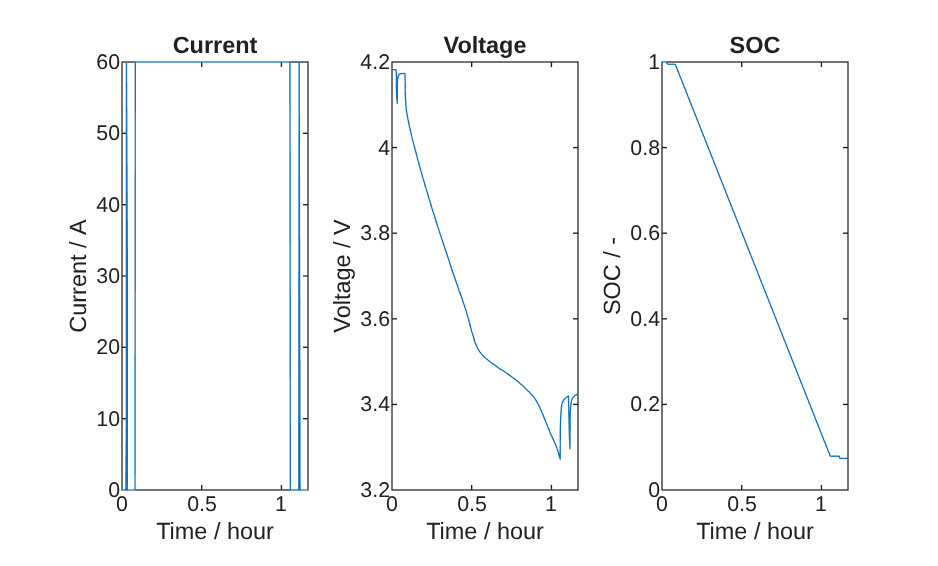

figure
tiledlayout(1, 3)
nexttile
plot(t/hour, I)
title('Current')
xlabel('Time / hour')
ylabel('Current / A');
nexttile
plot(t/hour, U)
title('Voltage')
xlabel('Time / hour')
ylabel('Voltage / V');
nexttile
plot(t/hour, SOC)
title('SOC')
xlabel('Time / hour')
ylabel('SOC / -');